clear variables; close all; clc;
addpath utilities\

addpath 1_g_h_filter\

## Building Intuition via Thought Experiments

Imagine that we live in a world without scales - the devices you  stand on to weigh yourself. One day at work a co-worker comes running up to you and announces her invention of a 'scale' to you. After she  explains, you eagerly stand on it and announce the results: "172 lbs".  You are ecstatic - for the first time in your life you know what you  weigh. More importantly, dollar signs dance in your eyes as you imagine  selling this device to weight loss clinics across the world! This is  fantastic!

Another co-worker hears the commotion and comes over to find out what has you so excited. You explain the invention and once again step onto  the scale, and proudly proclaim the result: "161 lbs." And then you  hesitate, confused.

"It read 172 lbs a few seconds ago", you complain to your co-worker.

"I never said it was accurate," she replies.

Sensors are inaccurate. This is the motivation behind a huge body of  work in filtering, and solving this problem is the topic of this book. I could just provide the solutions that have been developed over the last half century, but these solutions were developed by asking very basic,  fundamental questions into the nature of what we know and how we know  it. Before we attempt the math, let's follow that journey of discovery,  and see if it informs our intuition about filtering.

**Try Another Scale**

Is there any way we can improve upon this result? The obvious, first  thing to try is get a better sensor. Unfortunately, your co-worker  informs you that she has built 10 scales, and they all operate with  about the same accuracy. You have her bring out another scale, and you  weigh yourself on one, and then on the other. The first scale (A) reads  "160 lbs", and the second (B) reads "170 lbs". What can we conclude  about your weight?

Well, what are our choices?

- We could choose to only believe A, and assign 160lbs to our weight estimate.

- We could choose to only believe B, and assign 170lbs to our weight.

- We could choose a number less than both A and B.

- We could choose a number greater than both A and B.

- We could choose a number between A and B.

The first two choices are plausible, but we have no reason to favor  one scale over the other. Why would we choose to believe A instead of B? We have no reason for such a belief. The third and fourth choices are  irrational. The scales are admittedly not very accurate, but there is no reason at all to choose a number outside of the range of what they both measured. The final choice is the only reasonable one. If both scales  are inaccurate, and as likely to give a result above my actual weight as below it, more often than not the answer is somewhere between A and B.

In mathematics this concept is formalized as [*expected value*](https://en.wikipedia.org/wiki/Expected_value), and we will cover it in depth later. For now ask yourself what would be the 'usual' thing to happen if we took one million readings. Some of  the times both scales will read too low, sometimes both will read too  high, and the rest of the time they will straddle the actual weight. If  they straddle the actual weight then certainly we should choose a number between A and B. If they don't straddle then we don't know if they are  both too high or low, but by choosing a number between A and B we at  least mitigate the effect of the worst measurement. For example, suppose our actual weight is 180 lbs. 160 lbs is a big error. But if we choose a weight between 160 lbs and 170 lbs our estimate will be better than 160 lbs. The same argument holds if both scales returned a value greater  than the actual weight.

We will deal with this more formally later, but for now I hope it is clear that our best estimate is the average of A and B.


$$\frac{160+170}{2}=165$$


We can look at this graphically. I have plotted the measurements of A and B with an assumed error of  8 lbs. The measurements falls between 160 and 170 so the only weight that makes sense must lie within 160 and 170 lbs.

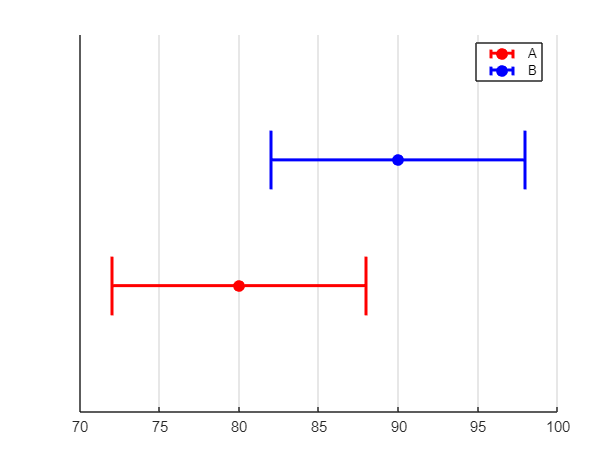

A = 80;
B = 90;
error_A = 8;
error_B = 8;

figure(); hold on; set(gca, 'XGrid', 'on'); legend('Location', "best");
errorbar(A, 1, error_A, 'horizontal', 'o', 'Color', 'red', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'DisplayName', 'A', 'CapSize', 40)
errorbar(B, 2, error_B, 'horizontal', 'o', 'Color', 'blue', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'DisplayName', 'B', 'CapSize', 40)
xlim([70 100]); ylim([0 3]); yticklabels(''); yticks('')

%exportgraphics(gcf, 'intuition1.pdf', 'ContentType', 'vector')

So 165 lbs looks like a reasonable estimate, but there is more  information here that we might be able to take advantage of. The only  weights that are possible lie in the intersection between the error bars of A and B. For example, a weight of 161 lbs is impossible because  scale B could not give a reading of 170 lbs with a maximum error of 8  pounds. Likewise a weight of 169 lbs is impossible because scale A could not give a reading of 160 lbs with a maximum error of 8 lbs. In this  example the only possible weights lie in the range of 162 to 168 lbs.

That doesn't yet allow us to find a better weight estimate, but let's play 'what if' some more. What if we are now told that A is three times more accurate than B? Consider the 5 options we listed above. It still  makes no sense to choose a number outside the range of A and B, so we  will not consider those. It perhaps seems more compelling to choose A as our estimate - after all, we know it is more accurate, why not use it  instead of B? Can B possibly improve our knowledge over A alone?

The answer, perhaps counter intuitively, is yes, it can. First, let's look at the same measurements of A=160 and B=170, but with the error of A  3 lbs and the error of B is 3 times as much,  9 lbs.

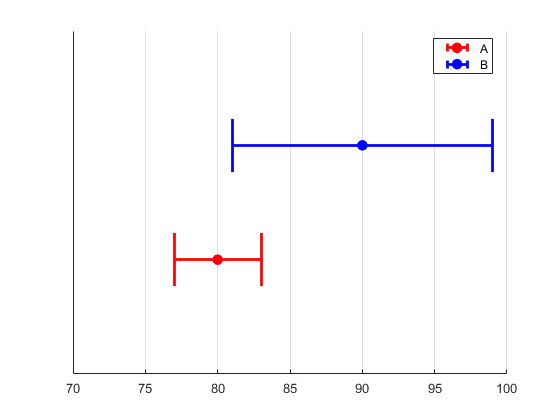

error_A = 3;
error_B = 9;

figure(); hold on; set(gca, 'XGrid', 'on'); legend('Location', "best");
errorbar(A, 1, error_A, 'horizontal', 'o', 'Color', 'red', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'DisplayName', 'A', 'CapSize', 40)
errorbar(B, 2, error_B, 'horizontal', 'o', 'Color', 'blue', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'DisplayName', 'B', 'CapSize', 40)
xlim([70 100]); ylim([0 3]); yticklabels(''); yticks('')

% exportgraphics(gcf, 'intuition2.pdf', 'ContentType', 'vector')

The overlap of the error bars of A and B are the only possible true  weight. This overlap is smaller than the error in A alone. More  importantly, in this case we can see that the overlap doesn't include  160 lbs or 165 lbs. If we only used the measurement from A because it is more accurate than B we would give an estimate of 160 lbs. If we  average A and B we would get 165 lbs. Neither of those weights are  possible given our knowledge of the accuracy of the scales. By including the measurement of B we would give an estimate somewhere between 161  lbs and 163 lbs, the limits of the intersections of the two error bars.

Let's take this to the extreme limits.  Assume we know scale A is  accurate to 1 lb. In other words, if we truly weigh 170 lbs, it could  report 169, 170, or 171 lbs. We also know that scale B is accurate to 9  lbs. We do a weighing on each scale, and get A=160, and B=170. What  should we estimate our weight to be? Let's look at that graphically.

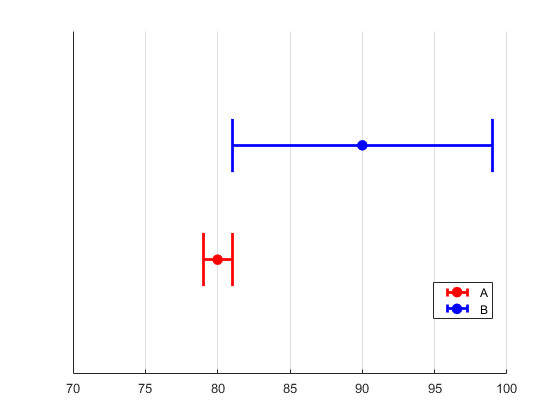

error_A = 1;
error_B = 9;

figure(); hold on; set(gca, 'XGrid', 'on'); legend('Location', "best");
errorbar(A, 1, error_A, 'horizontal', 'o', 'Color', 'red', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'DisplayName', 'A', 'CapSize', 40)
errorbar(B, 2, error_B, 'horizontal', 'o', 'Color', 'blue', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'DisplayName', 'B', 'CapSize', 40)
xlim([70 100]); ylim([0 3]); yticklabels(''); yticks('')

% exportgraphics(gcf, 'intuition3.pdf', 'ContentType', 'vector')

Here we can see that the only possible weight is 161 lbs. This is an  important result. With two relatively inaccurate sensors we are able to  deduce an extremely accurate result.

**So two sensors, even if one is less accurate than the other, is better than one.** I will harp on this for the remainder of the book. We never throw  information away, no matter how poor it is. We will be developing math  and algorithms that allow us to include all possible sources of  information to form the best estimate possible.

However, we have strayed from our problem. No customer is going to  want to buy multiple scales, and besides, we initially started with an  assumption that all scales were equally (in)accurate. This insight of  using all measurements regardless of accuracy will play a large role  later, so don't forget it.

What if I have one scale, but I weigh myself many times? We concluded that if we had two scales of equal accuracy we should average the  results of their measurements. What if I weigh myself 10,000 times with  one scale? We have already stated that the scale is equally likely to  return a number too large as it is to return one that is too small. It  is not that hard to prove that the average of a large number of weights  will be very close to the actual weight, but let's write a simulation  for now.

N = 10000;
measurements = A + (B-A).*rand(N,1);
mean(measurements)

ans = 85.0262

The exact number printed depends on your random number generator, but it should be very close to 165.

This code makes one assumption that probably isn't true - that the  scale is as likely to read 160 as 165 for a true weight of 165 lbs. This is almost never true. Real sensors are more likely to get readings  nearer the true value, and are less and less likely to get readings the  further away from the true value it gets. We will cover this in detail  in the Gaussian chapter. For now, I will use without further explanation the `numpy.random.normal()` function, which will produce  more values nearer 165 lbs, and fewer further away. Take it on faith for now that this will produce noisy measurements similar to how a real scale works.

mu = 165;
sigma = 1;
measurements = sigma.*randn(N,1) + mu;
mean(measurements)

ans = 165.0209

Again the answer is very close to 165.

Okay, great, we have an answer to our sensor problem! But it is not a very practical answer. No one has the patience to weigh themselves ten  thousand, or even a dozen times.

So, let's play 'what if'. What if you measured your weight once a  day, and got the readings 170, 161, and then 169. Did you gain weight,  lose weight, or is this all just noisy measurements?

We really can't say. The first measurement was 170, and the last was  169, implying a 1 lb loss. But if the scale is only accurate to 10 lbs,  that is explainable by noise. I could have actually gained weight; maybe my weight on day one was 165 lbs, and on day three it was 172. It is  possible to get those weight readings with that weight gain. My scale  tells me I am losing weight, and I am actually gaining weight! Let's  look at that in a chart. I've plotted the measurements along with the  error bars, and then some possible weight gain/losses that could be  explained by those measurements in dotted green lines.

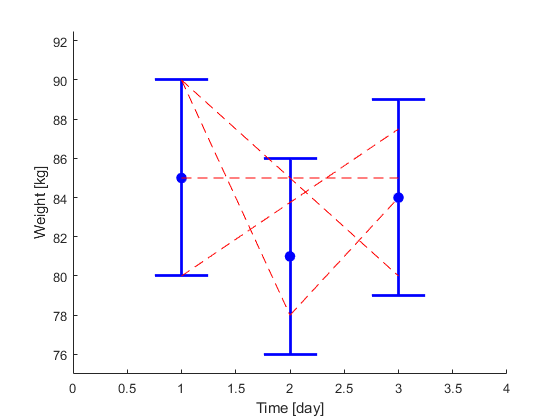

days = 1:3;
weighs = [85 81 84];
errors = [10 10 10]/2;

figure(); hold on;
errorbar(days, weighs, errors, 'o', 'Color', 'blue', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'CapSize', 40)
line([1 3], [170 170]/2, 'LineStyle', '--', 'Color', 'red')
line([1 3], [160 175]/2, 'LineStyle', '--', 'Color', 'red')
line([1 3], [180 160]/2, 'LineStyle', '--', 'Color', 'red')
line([1 2], [90 78], 'LineStyle', '--', 'Color', 'red')
line([2 3], [78 84], 'LineStyle', '--', 'Color', 'red')
xlim([0 4]); ylim([150/2 185/2]); ylabel('Weight [kg]'); xlabel('Time [day]')

% exportgraphics(gcf, 'hyps.pdf', 'ContentType', 'vector')

As we can see there is an extreme range of weight changes that could  be explained by these three measurements. In fact, there are an infinite number of choices. Shall we give up? Not me! Recall that we are talking about measuring a human's weight. There is no reasonable way for a  human to weigh 180 lbs on day 1 and 160 lbs on day 3. or to lose 30 lbs  in one day only to gain it back the next (we will assume no amputations  or other trauma has happened to the person).

The behavior of the physical system we are measuring should influence how we interpret the measurements. If we were weighing a rock each day  we'd attribute all of the variance to noise. If we were weighing a  cistern fed by rain and used for household chores we might believe such  weight changes are real.

Suppose I take a different scale, and I get the following  measurements: 169, 170, 169, 171, 170, 171, 169, 170, 169, 170. What  does your intuition tell you? It is possible, for example, that you  gained 1 lb each day, and the noisy measurements just happens to look  like you stayed the same weight. Equally, you could have lost 1 lb a day and gotten the same readings. But is that likely? How likely is it to  flip a coin and get 10 heads in a row? Not very likely. We can't prove  it based solely on these readings, but it seems pretty likely that my  weight held steady. In the chart below I've plotted the measurements  with error bars, and a likely true weight in dashed green. This dashed  line is not meant to be the 'correct' answer to this problem, merely one that is reasonable and could be explained by the measurement.

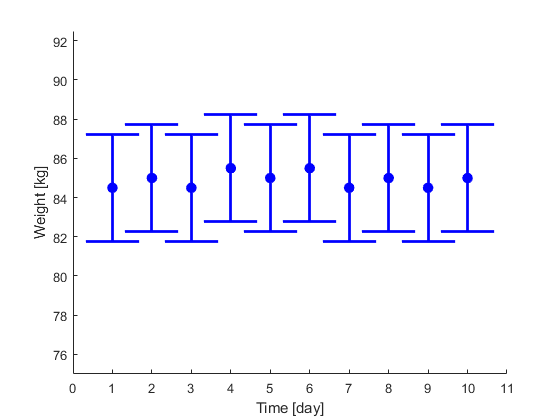

days = 1:10;
weighs = [169, 170, 169, 171, 170, 171, 169, 170, 169, 170]/2;
errors = 6.*ones(10, 1)/2.2;

figure(); hold on;
errorbar(days, weighs, errors, 'o', 'Color', 'blue', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'CapSize', 40)
line([1 10], [169 170], 'LineStyle', '--', 'Color', 'red')
xlim([0 11]); ylim([150 185]/2); ylabel('Weight [kg]'); xlabel('Time [day]')

Another what if: what if the readings were 158.0, 164.2, 160.3,  159.9, 162.1, 164.6, 169.6, 167.4, 166.4, 171.0? Let's look at a chart  of that and then answer some questions.

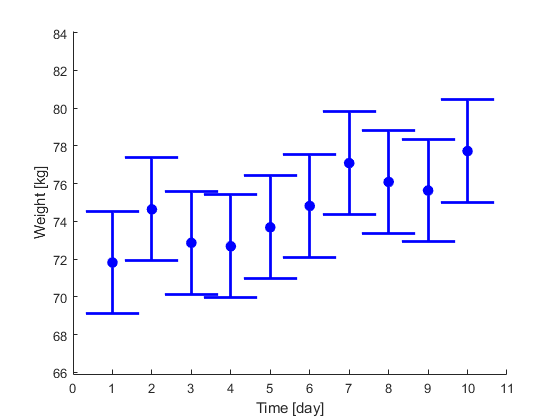

weighs = [158.0, 164.2, 160.3, 159.9, 162.1, 164.6, 169.6, 167.4, 166.4, 171.0]/2.2;

figure(); hold on;
errorbar(days, weighs, errors, 'o', 'Color', 'blue', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'CapSize', 40)
xlim([0 11]); ylim([145 185]/2.2); ylabel('Weight [kg]'); xlabel('Time [day]')

Does it 'seem' likely that I lost weight and this is just really  noisy data? Not really. Does it seem likely that I held the same weight? Again, no. This data trends upwards over time; not evenly, but  definitely upwards. We can't be sure, but that looks like a weight gain, and a significant weight gain at that. Let's test this assumption with  some more plots. It is often easier to 'eyeball' data in a chart versus a table.

So let's look at two hypotheses. First, let's assume our weight did not change. To get that number we agreed that we should average the  measurements. Let's look at that.

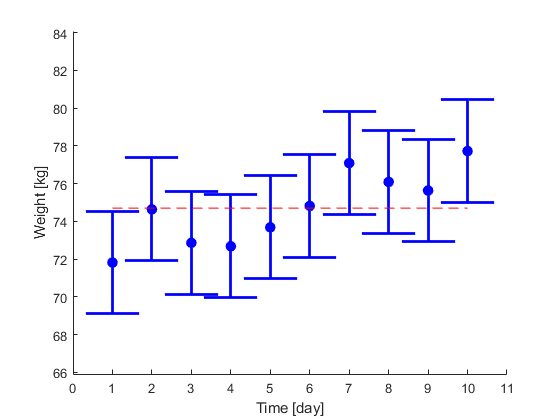

figure(); hold on;
errorbar(days, weighs, errors, 'o', 'Color', 'blue', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'CapSize', 40)
estimate = mean(weighs);
line([1 10], [estimate estimate], 'LineStyle', '--', 'Color', 'red')
xlim([0 11]); ylim([145 185]/2.2); ylabel('Weight [kg]'); xlabel('Time [day]')

%  exportgraphics(gcf, 'constantHypothesis.pdf', 'ContentType', 'vector')

That doesn't look very convincing. In fact, we can see that there is  no horizontal line that we could draw that is inside all of the error  bars.

Now, let's assume we gained weight. How much? I don't know, but NumPy does! We want to draw a line through the measurements that looks  'about' right. NumPy has functions that will do this according to a rule called "least squares fit". Let's not worry about the details of that  computation (I use [polyfit()](https://docs.scipy.org/doc/numpy/reference/generated/numpy.polyfit.html) if you are interested), and just plot the results.

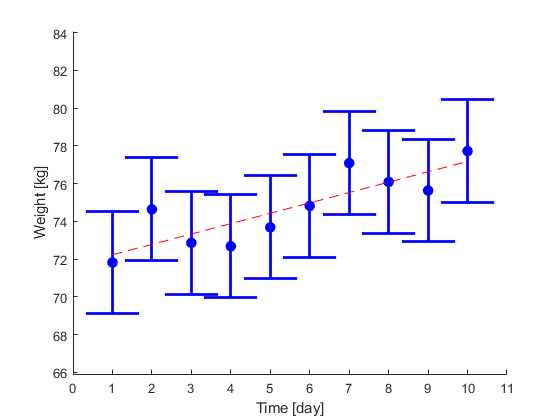

figure(); hold on;
errorbar(days, weighs, errors, 'o', 'Color', 'blue', 'LineWidth', 2, 'MarkerFaceColor', "auto", 'CapSize', 40)
p = polyfit(days, weighs, 1);
estimate = polyval(p, [1 10]);
line([1 10], estimate, 'LineStyle', '--', 'Color', 'red')
xlim([0 11]); ylim([145 185]/2.2); ylabel('Weight [kg]'); xlabel('Time [day]')

%  exportgraphics(gcf, 'upwardHypothesis.pdf', 'ContentType', 'vector')

his looks much better, at least to my eyes. Notice now the hypothesis lies very close to each measurement, whereas in the previous plot the  hypothesis was often quite far from the measurement. It seems far more  likely to be true that I gained weight than I didn't gain any weight.  Did I actually gain 13 lbs? Who can say? That seems impossible to  answer.

"But is it impossible?" pipes up a co-worker.

Let's try something crazy. Let's assume that I know I am gaining  about one lb a day. It doesn't matter how I know that right now, assume I know it is approximately correct. Maybe I am on a 6000 calorie a day  diet, which would result in such a weight gain. Or maybe there is  another way to estimate the weight gain. This is a thought experiment,  the details are not important. Let's see if we can make use of such  information if it was available.

The first measurement was 158. We have no way of knowing any  different, so let's accept that as our estimate. If our weight today is  158, what will it be tomorrow? Well, we think we are gaining weight at 1 lb/day, so our prediction is 159, like so:

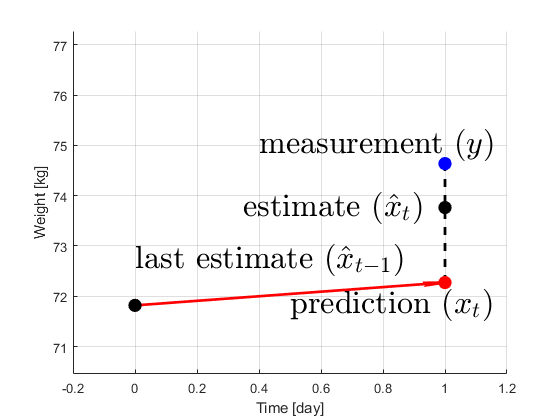

figure(); hold on; grid on; axis('manual')
arrow([0 158/2.2], [1 159/2.2], 'Linewidth', 2, 'Color', 'red', 'BaseAngle', 60, 'Length', 30) 
%line([0 1], [158 159]/2.2, 'LineWidth', 2, 'Color', 'red')
scatter(0, 158/2.2, 100, 'black', "filled")
text(0, 160/2.2, 'last estimate $$(\hat{x}_{t-1})$$', 'Interpreter', "latex", 'FontSize', 24)
text(0.35, 162.28/2.2, 'estimate $$(\hat{x}_t)$$', 'Interpreter', "latex", 'FontSize', 24)
text(0.5, 158/2.2, 'prediction $$(x_t)$$', 'Interpreter', "latex", 'FontSize', 24)
text(0.4, 165/2.2, 'measurement $$(y)$$', 'Interpreter', "latex", 'FontSize', 24)
line([1 1], [159 164.2]/2.2, 'LineWidth', 2, 'LineStyle', '--', 'Color', 'black')
scatter(0, 158/2.2, 100, 'black', "filled")
scatter(1, 159/2.2, 100, 'red', "filled")
scatter(1, 164.2/2.2, 100, 'blue', "filled")
scatter(1, 162.28/2.2, 100, 'black', "filled")

ylim([155 170]/2.2); xlim([-0.2 1.2]); ylabel('Weight [kg]'); xlabel('Time [day]')

%exportgraphics(gcf, 'predictionMeasurement.pdf', 'ContentType', 'vector')

kay, but what good is this? Sure, we could assume the 1 lb/day is  accurate, and predict our weight for the next 10 days, but then why use a scale at all if we don't incorporate its readings? So let's look at the next measurement. We step on the scale again and it displays 164.2 lbs.

weights = [158.0, 164.2, 160.3, 159.9, 162.1, 164.6, 169.6, 167.4, 166.4, 171.0, 171.2, 172.6]/2.2;
days = 1 : 1 : length(weights);
time_step = 1;
gain_rate = 1;
scale_factor = 4/10;
initial_weight = 160/2.2;
estimated_weight = initial_weight;
for ii = 1 : length(days)
    predicted_weight = estimated_weight + gain_rate * time_step
    estimated_weight = predicted_weight + scale_factor * (weights(ii) - predicted_weight)
    preds(ii) = predicted_weight;
    corrs(ii) = estimated_weight;
end

predicted_weight = 71.7273

estimated_weight = 71.7636

predicted_weight = 70.7636

estimated_weight = 72.3127

predicted_weight = 71.3127

estimated_weight = 71.9331

predicted_weight = 70.9331

estimated_weight = 71.6326

predicted_weight = 70.6326

estimated_weight = 71.8523

predicted_weight = 70.8523

estimated_weight = 72.4386

predicted_weight = 71.4386

estimated_weight = 73.6995

predicted_weight = 72.6995

estimated_weight = 74.0561

predicted_weight = 73.0561

estimated_weight = 74.0882

predicted_weight = 73.0882

estimated_weight = 74.9438

predicted_weight = 73.9438

estimated_weight = 75.4936

predicted_weight = 74.4936

estimated_weight = 76.0780

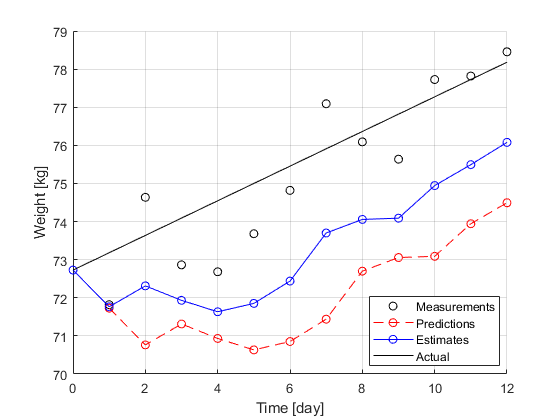

figure(); hold on; grid on;
plot(days,weights,'ko','DisplayName','Measurements');
hold on;grid on;
plot(days,preds,'r--o','DisplayName','Predictions');
plot([0 days],[initial_weight corrs],'b-o','DisplayName','Estimates');
line([0 12], [160 172]/2.2, 'Color', 'k', 'DisplayName', 'Actual')
%plot(days, values,'k--','DisplayName','values');
legend('Location','best');
 ylabel('Weight [kg]'); xlabel('Time [day]')

%exportgraphics(gcf, 'gh1.pdf', 'ContentType', 'vector')

weights = [158.0, 164.2, 160.3, 159.9, 162.1, 164.6, 169.6, 167.4, 166.4, 171.0, 171.2, 172.6]/2.2;
days = 1 : 1 : length(weights);
time_step = 1;
gain_rate = -1;
scale_factor = 4/10;
initial_weight = 160/2.2;
estimated_weight = initial_weight;
for ii = 1 : length(days)
    predicted_weight = estimated_weight + gain_rate * time_step
    estimated_weight = predicted_weight + scale_factor * (weights(ii) - predicted_weight)
    preds(ii) = predicted_weight;
    corrs(ii) = estimated_weight;
end

predicted_weight = 71.7273

estimated_weight = 71.7636

predicted_weight = 70.7636

estimated_weight = 72.3127

predicted_weight = 71.3127

estimated_weight = 71.9331

predicted_weight = 70.9331

estimated_weight = 71.6326

predicted_weight = 70.6326

estimated_weight = 71.8523

predicted_weight = 70.8523

estimated_weight = 72.4386

predicted_weight = 71.4386

estimated_weight = 73.6995

predicted_weight = 72.6995

estimated_weight = 74.0561

predicted_weight = 73.0561

estimated_weight = 74.0882

predicted_weight = 73.0882

estimated_weight = 74.9438

predicted_weight = 73.9438

estimated_weight = 75.4936

predicted_weight = 74.4936

estimated_weight = 76.0780


figure(); hold on; grid on;
plot(days,weights,'ko','DisplayName','Measurements');
hold on;grid on;
plot(days,preds,'r--o','DisplayName','Predictions');
plot([0 days],[initial_weight corrs],'b-o','DisplayName','Estimates');
line([0 12], [160 172]/2.2, 'Color', 'k', 'DisplayName', 'Actual')
%plot(days, values,'k--','DisplayName','values');
legend('Location','best');
 ylabel('Weight [kg]'); xlabel('Time [day]')

 %exportgraphics(gcf, 'gh2.pdf', 'ContentType', 'vector')

weights = [158.0, 164.2, 160.3, 159.9, 162.1, 164.6, 169.6, 167.4, 166.4, 171.0, 171.2, 172.6]/2.2;
days = 1 : 1 : length(weights);
time_step = 1;
gain_rate = -1;
scale_factor = 4/10;
gain_scale = 1/3;
initial_weight = 160/2.2;
estimated_weight = initial_weight;
for ii = 1 : length(days)
    predicted_weight = estimated_weight + gain_rate * time_step

    residual = (weights(ii) - predicted_weight);
    gain_rate = gain_rate + gain_scale * (residual/time_step);
    estimated_weight = predicted_weight + scale_factor * residual

    preds(ii) = predicted_weight;
    corrs(ii) = estimated_weight;
end

predicted_weight = 71.7273

residual = 0.0909

gain_rate = -0.9697

estimated_weight = 71.7636

predicted_weight = 70.7939

residual = 3.8424

gain_rate = 0.3111

estimated_weight = 72.3309

predicted_weight = 72.6420

residual = 0.2216

gain_rate = 0.3850

estimated_weight = 72.7307

predicted_weight = 73.1156

residual = -0.4338

gain_rate = 0.2404

estimated_weight = 72.9421

predicted_weight = 73.1825

residual = 0.4993

gain_rate = 0.4068

estimated_weight = 73.3822

predicted_weight = 73.7890

residual = 1.0291

gain_rate = 0.7499

estimated_weight = 74.2007

predicted_weight = 74.9506

residual = 2.1404

gain_rate = 1.4633

estimated_weight = 75.8067

predicted_weight = 77.2700

residual = -1.1791

gain_rate = 1.0703

estimated_weight = 76.7984

predicted_weight = 77.8687

residual = -2.2323

gain_rate = 0.3262

estimated_weight = 76.9757

predicted_weight = 77.3019

residual = 0.4254

gain_rate = 0.4680

estimated_weight = 77.4721

predicted_weight = 77.9400

residual = -0.1218

gain_rate = 0.4274

estimated_weight = 77.8913

predicted_weight = 78.3186

residual = 0.1359

gain_rate = 0.4727

estimated_weight = 78.3730

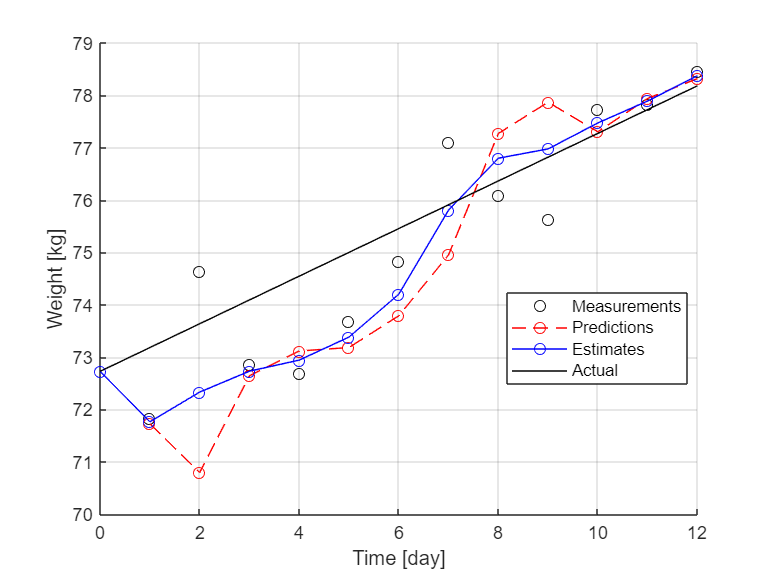


figure(); hold on; grid on;
plot(days,weights,'ko','DisplayName','Measurements');
hold on;grid on;
plot(days,preds,'r--o','DisplayName','Predictions');
plot([0 days],[initial_weight corrs],'b-o','DisplayName','Estimates');
line([0 12], [160 172]/2.2, 'Color', 'k', 'DisplayName', 'Actual')
%plot(days, values,'k--','DisplayName','values');
legend('Location','best');
 ylabel('Weight [kg]'); xlabel('Time [day]')

 %exportgraphics(gcf, 'gh3.pdf', 'ContentType', 'vector')
